clear
close all
clc
seed = 1234

seed = 1234

rng(seed);
FNT_SZ = 16;

%% Set the LPA parameters

% maximum degree of polynomial used for fitting
N = 1;

% parameter for the confidence intervals in the ICI rule
Gamma = 2;

% Set all the scale values
hmax = 21;
all_h = 1:hmax;

% set all the direction values
all_theta = 1:4;

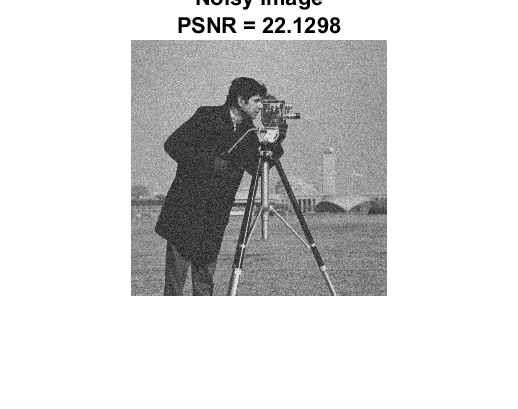

%% Generate Signal

% load the cameraman image
y = im2double(imread('cameraman.tif'));

% noise standard deviation
sigma = 20/255;

% noisy signal
s = y + sigma*randn(size(y));
figure, imshow(s, []);
psnr = 10 * log10(1/mean((s-y).^2, "all"));
title({'Noisy Image', ['PSNR = ', num2str(psnr)]})


%% generate the LPA kernels for all the scale

all_g = cell(length(all_h),length(all_theta));
for jj=1:length(all_theta)
    for ii=1:length(all_h)
        h = all_h(ii);
        
        % define the weights 
        w = zeros(2*h-1, 2*h-1);
        %define the block of ones, it seems a complicated way but it works!
        w((round(jj/2)-1)*floor(end/2)+(1:round(end/2)), (mod(jj-1,2))*floor(end/2)+(1:round(end/2))) = 1;        
        % compute and store the kernel g
        g = compute_LPA_kernel(w, N);
        all_g{ii, jj} = g;
    end
end

%% find the best scale for each sample using the LPA-ICI rule

% initialize the weights matrix
weights = zeros(size(s, 1), size(s, 2));

% initialize the aggregate estimate image
sfinal = zeros(size(s));

% loop over the directions
for jj=1:length(all_theta)
    
    % initialize the estimate corresponding to the theta_jj
    stheta = zeros(size(s));
    
    % initialize the matrix containing all the variances
    vartheta = zeros(size(s));
    
    % initialize the lower and upper bound vectors
    lower_bounds = -ones(size(s))*Inf;
    upper_bounds = ones(size(s))*Inf;
    
    % loop over all the scales
    for ii=1:length(all_h)
        
        h = all_h(ii);
        g = all_g{ii, jj};
        
        % compute the estimate for the scale h
        shat = conv2(s, g, "same");
        
        % compute the lower and upper bound of the confidence interval for this
        % scale
        lb = shat - Gamma*sigma*norm(g, 2);
        ub = shat + Gamma*sigma*norm(g, 2);
        
        % update the lower and upper bounds
        lower_bounds = max(lower_bounds, lb);
        upper_bounds = min(upper_bounds, ub);
        
        % update the theta_jj estimate
        %upgrade sfinal until upper_bounds<lower_bounds
        idx = find(upper_bounds > lower_bounds);
        stheta(idx) = shat(idx);
        
        % compute the variance and update the vartheta matrix
        vartheta(idx) = 1/(sigma * norm(g, 2))^2;
    end
    
    % update sfinal and the weights
    sfinal = sfinal + vartheta.*stheta;
    weights = weights + vartheta;
end

% normalize w.r.t. the weights
sfinal(weights>0) = sfinal(weights>0)./weights(weights>0);

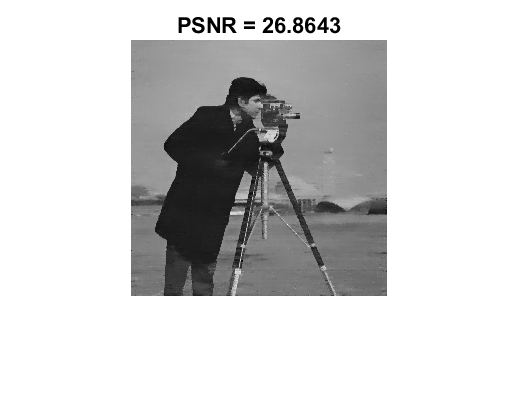

%% 
% compute the psnr
psnr = 10 *log10(1/mean((sfinal - y).^2, "all")); 

close all
figure, imshow(sfinal, []);
title(['PSNR = ', num2str(psnr)])